## 2.4 Exercises

### 1

A) Less flexible method would perform better. With a large sample size there will be more points to overfit to. Aka a lot of samples provides a lot of variance for a high variance model to conform to.

B) More flexible method would perform better. With a large number of predictors the true function *f *may have a high bias and need a flexible model to capture its behaviour. Plus a small number of observations will mean less variance in the input data

C) More flexible method would perform better. Less flexible methods tend towards linear fits which would introduce a high bias for a non-linear relationship

D) Less flexible method would perform better. The high variance of a highly flexible model would not be suitable for a high vairence error rate input

### 2

A) Inference. n = 500, p = 4

B) Prediction. n = 20, p = 14

C) Prediction. n = 52, p = 4

### 3

A) 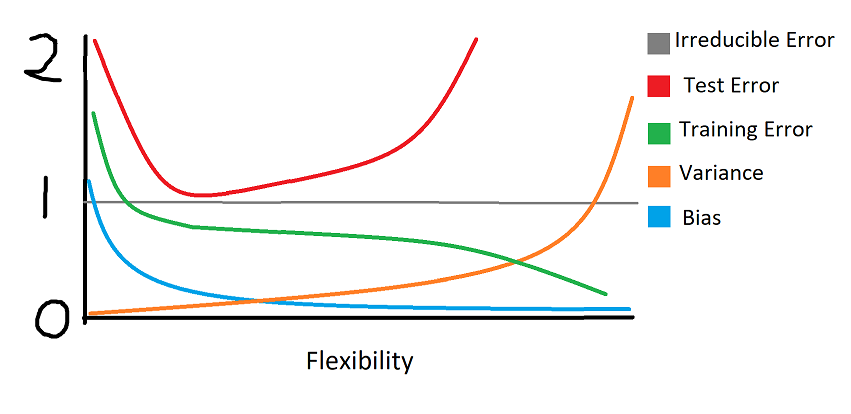

## 7

A)

O = zeros(6,3);
X = [[0,3,0];
    [2,0,0];
    [0,1,3];
    [0,1,2];
    [-1,0,1];
    [1,1,1]];
distance = NaN(6,1);
for i = 1:6
    distance(i) = euclid(O(i,:), X(i,:));
end
distance

distance =     3.0000
    2.0000
    3.1623
    2.2361
    1.4142
    1.7321


B) 

[val, index] = min(distance) % index = 5, therefore green!

val = 1.4142

index = 5

C)

Minimum 3 are Obs 2,5,6 therefore Red!

D)

Small, which gives a more flexible k means

## 8

% Load in data
college = readtable("College.csv");

college_data = table2array(college(:,3:end));
column_means = mean(college_data)

column_means = 1.0e+04 *

    0.3002    0.2019    0.0780    0.0028    0.0056    0.3700    0.0855    1.0441    0.4358    0.0549    0.1341    0.0073    0.0080    0.0014    0.0023    0.9660    0.0065


disp(college.Properties.VariableNames(3:end))

  Columns 1 through 12

    {'Apps'}    {'Accept'}    {'Enroll'}    {'Top10perc'}    {'Top25perc'}    {'F_Undergrad'}    {'P_Undergrad'}    {'Outstate'}    {'Room_Board'}    {'Books'}    {'Personal'}    {'PhD'}

  Columns 13 through 17

    {'Terminal'}    {'S_F_Ratio'}    {'perc_alumni'}    {'Expend'}    {'Grad_Rate'}



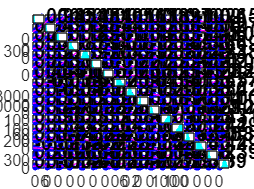

figure
corrplot(college_data)

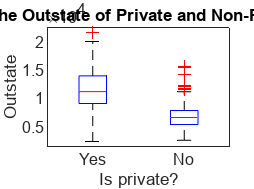

boxplot(college_data(:,8), table2array(college(:,2)))
ylabel("Outstate")
xlabel("Is private?")
title("Boxplots showing the Outstate of Private and Non-Private US Universities")

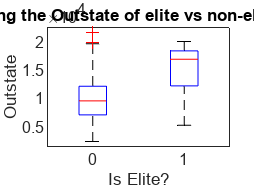

college.Elite = college.Top10perc > 50;
boxplot(college.Outstate, college.Elite)
title("Boxplots showing the Outstate of elite vs non-elite US Universities")
ylabel("Outstate")
xlabel("Is Elite?")

### **9**

auto = readtable("Auto.csv")

auto = 397×9 table
    mpg    cylinders    displacement    horsepower    weight    acceleration    year    origin                name             
    ___    _________    ____________    __________    ______    ____________    ____    ______    _____________________________

    18         8            307            130         3504           12         70       1       {'chevrolet chevelle malibu'}
    15         8            350            165         3693         11.5         70       1       {'buick skylark 320'        }
    18         8            318            150         3436           11         70       1       {'plymouth satellite'       }
    16         8            304   

auto = auto(~any(ismissing(auto),2),:)

auto = 392×9 table
    mpg    cylinders    displacement    horsepower    weight    acceleration    year    origin                name             
    ___    _________    ____________    __________    ______    ____________    ____    ______    _____________________________

    18         8            307            130         3504           12         70       1       {'chevrolet chevelle malibu'}
    15         8            350            165         3693         11.5         70       1       {'buick skylark 320'        }
    18         8            318            150         3436           11         70       1       {'plymouth satellite'       }
    16         8            304   

#### A

**Quantitative: **mpg, cylinders, displacement, horsepower, weight, acceleration, year

**Qualatitive: **origin

**B**

ranges = range(auto{:,1:7},1)

ranges = 1.0e+03 *

    0.0376    0.0050    0.3870    0.1840    3.5270    0.0168    0.0120


**C**

means = mean(auto{:,1:7},1)

means = 1.0e+03 *

    0.0234    0.0055    0.1944    0.1045    2.9776    0.0155    0.0760


stds = std(auto{:,1:7},1) 

stds =     7.7950    1.7036  104.5104   38.4420  848.3184    2.7553    3.6790


**D**

auto_small = auto

auto_small = 392×9 table
    mpg    cylinders    displacement    horsepower    weight    acceleration    year    origin                name             
    ___    _________    ____________    __________    ______    ____________    ____    ______    _____________________________

    18         8            307            130         3504           12         70       1       {'chevrolet chevelle malibu'}
    15         8            350            165         3693         11.5         70       1       {'buick skylark 320'        }
    18         8            318            150         3436           11         70       1       {'plymouth satellite'       }
    16         8            

auto_small(10:85,:) = []

auto_small = 316×9 table
    mpg    cylinders    displacement    horsepower    weight    acceleration    year    origin                name             
    ___    _________    ____________    __________    ______    ____________    ____    ______    _____________________________

    18         8            307            130         3504           12         70       1       {'chevrolet chevelle malibu'}
    15         8            350            165         3693         11.5         70       1       {'buick skylark 320'        }
    18         8            318            150         3436           11         70       1       {'plymouth satellite'       }
    16         8            


ranges_small = range(auto_small{:,1:7},1)

ranges_small = 1.0e+03 *

    0.0356    0.0050    0.3870    0.1840    3.3480    0.0163    0.0120


means_small = mean(auto_small{:,1:7},1)

means_small = 1.0e+03 *

    0.0244    0.0054    0.1872    0.1007    2.9360    0.0157    0.0771


stds_small = std(auto_small{:,1:7},1) 

stds_small =     7.8548    1.6516   99.5205   35.6523  810.0155    2.6895    3.1013


**E**

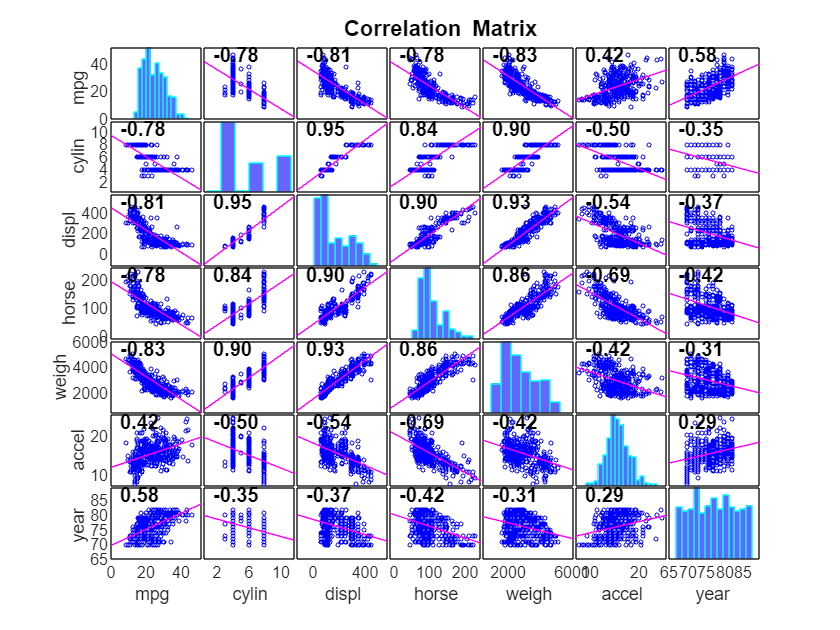

corrplot(auto(:,1:7))

**F**

ALL OF THEM. THROW IN BIG NEURAL NET, LET AI DO THING